Npt = 2^10; % nº de pontos discretizados
n = (-Npt/2:1:Npt/2 -1); % vetor que guarda essa informação


ti = -3; % tempo inicial da análise
tf = -ti; % tempo final da análise 
Ts = (tf - ti)/Npt; % período amostral 
t = n*Ts; % vetor tempo discretizado

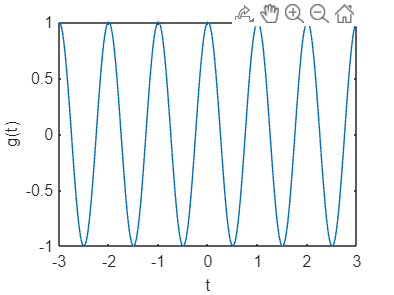

g = t*0; % inicia a função g com o msm nº de pontos de t

g = cos(2*pi*1*t); % função discretizada

plot(t, g)
xlabel('t')
ylabel('g(t)') % Plota o gráfico da g(t)

% Processo análogo a segunda sessão
Npt_v = 2^11;
k = (-Npt_v/2:1:Npt_v/2 -1);
vi = -1;
vf = -vi;
v_step = (vf - vi)/Npt_v;
v = k*v_step;

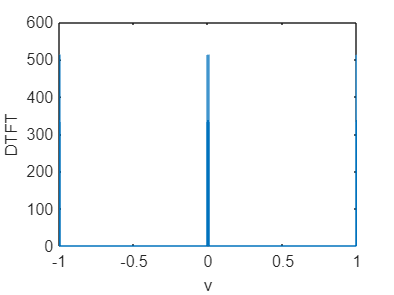

G_DTFT = v*0; %inicia a função G_DTFT com o msm nº de pontos de v

for u = 1:length(v)

    G_DTFT(u) = sum(g.*exp(-1i*2*pi*v(u)*n));

end % Faz a soma pra cada ponto do vetor v

figure(1)
plot(v, abs(G_DTFT))
xlabel('v')
ylabel('DTFT') % Plota o gráfico da DTFT

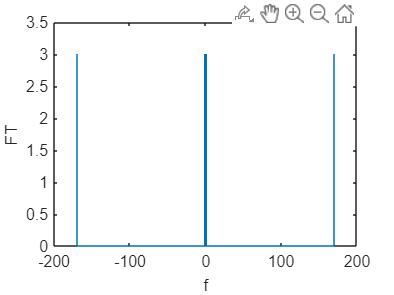

fs = 1/Ts;
f = v*fs;

G_FT = G_DTFT./fs;


plot(f, abs(G_FT))
xlabel('f')
ylabel('FT') % Plota o gráfico da DTFT